# CSX/ECE 6730 Project 1: Orbit Modeling

**Team 57: Blaine Costello, Caitlyn Caggia, Lakshmi Raju**

**March 1, 2019**

## INPUT SETUP

*Additional files: planetData.m*

**Mass Data**

Masses of the Sun and 9 planets (Mercury, Venus, Earth, Moon, Mars, Jupiter, Saturn, Uranus, Neptune, Pluto, respectively) courtesy of [NASA](https://ilrs.cddis.eosdis.nasa.gov/docs/2014/196C.pdf) [1]. Mass is saved as a 1xN vector as GM in au^3/day^2.

**Position and Velocity Data**

Initial position and velocity vectors were pulled from [NASA data](https://ilrs.cddis.eosdis.nasa.gov/docs/2014/196C.pdf) for June 28, 1969 [1].

The barycenter of the Solar System is used as the observation point of reference.  Distances are in au and velocities are in au/day. Positions and velocities are saved in 3xN vectors.

**Expected Values**

Actual positions and velocities for June 28, 1970 were pulled from NASA JPL data through Matlab's built-in `planetEphemeris()` function. These values have less significant figures than the data for 1969 above, but are useful to compare each model's calculations to the real position of each body.

Note that Matlab's Aerospace Toolbox (available with the Georgia Tech's Matlab licenses for free) as well as the Ephemeris Data add-on (available through [Mathworks](https://www.mathworks.com/matlabcentral/fileexchange/46671-ephemeris-data-for-aerospace-toolbox) for free) are needed to use this function. These packages use data from NASA's Jet Propulsion Laboratory (JPL) ephemeris [database](https://ssd.jpl.nasa.gov/?planet_eph_export) [2]. 

clear all; close all;
addpath('Data');
run planetData.m;

## COWELL'S METHOD

*Additional files: cowells.m, cowellsExample.avi*

**Background**

Cowell's method for orbital simulation simply sums the Newtonian forces on a body of *i *from the other bodies *j:*


$$\ddot{\mathbf{r}}_i = \sum_{j=1,{j \neq i}}^{n}   \frac{Gm_{j}( \mathbf{r}_j - \mathbf{r}_i)}{r_{ij}^3}$$


where

    $\ddot{\mathbf{r}}_i$ is the acceleration vector of body *i*

*    G *is the gravitational constant ($6.674 \times 10^{-11} \:\mathrm{m}^{3} \,\mathrm{kg}^{-1} \,\mathrm{s}^{-2}$)

    $m_j
$ is the mass of body j

    $\mathbf{r}_i$ and $\mathbf{r}_j$ are the position vectors of objects *i * and *j*

    $r_{ij}$ is the distance from object *i* to object *j*

with all vectors relative to the barycenter of the system as shown in Figure 1.

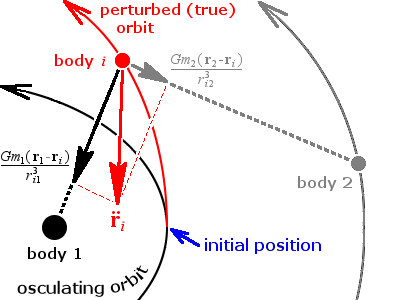

*Figure 1. Forces from preturbing bodies (black and gray) are summed to form the total force on the body of interest (red). Thus the true (red) orbit deviates from the original unpreturbed orbit (black). Image courtesy of *[*Wikimedia*](https://upload.wikimedia.org/wikipedia/commons/3/30/Cowells_method.png)*. *

While this method is the among the simplest to use, it has high error when handling large perturbations (for example, when two objects nearly miss each other) and requires a large degree of arithmetic precision when the mass of the bodies varies greatly [3].

**Cowell's Method Example**

The situation to be simulated is the orbital movement of a system of 10 bodies around the Sun: Mercury, Venus, Earth, Moon, Mars, Jupiter, Saturn, Uranus, Neptune, Pluto. To do this, Cowell's Method is used to estimate the perturbations of the bodies on each other and model the movement of the system. 

Run the simulation for one full year (on Earth).

addpath('Cowells');
[finalPos, finalVel] = cowells('cowellsExample.avi', 365, 100, true);
implay('cowellsExample.avi')

To get an accurate representation of the orbit, very small time steps are required. We tested three timesteps (0.1, 0.01, and 0.001 days) running for a total of 1000 days. Although the time steps seems small, they are actually still not small enought to accurately simulate the moon's trajectory. We are limited by computations, running a more accurate simulation for three years would require over 10GB of data, and take a lot longer than practical with our resources.  The resulting videos are too large to host in GitHub, so they are in Google drive: [https://drive.google.com/open?id=1y0ewrl9TxiLYopDY_j2Ry0_34iph4zjs.](https://drive.google.com/open?id=1y0ewrl9TxiLYopDY_j2Ry0_34iph4zjs.) 

The simulation was also run to simulate just the Moon around the Earth. The Cowell's Method code allows for N bodies, simply changing the constants in the planets.mat file which is loaded in line 10 in the cowells.m function to include the wanted bodies, allows for various simulations. 

load planets.mat masses positions velocities N;
masses11 = masses; positions11 = positions; velocities11 = velocities; N11 = N; %Saving old data
masses = masses11(4:5); positions = positions11(:,4:5); velocities = velocities11(:,4:5); N = 2;
save('planets', 'masses', 'positions', 'velocities', 'N');
[finalPos2, finalVel2] = cowells('cowellsExample2.avi', 365, 100, true);
implay('cowellsExample2.avi')
masses = masses11; positions = positions11; velocities = velocities11; N = N11;
%Reverting planets.mat back to 11 body system
save('planets', 'masses', 'positions', 'velocities', 'N'); 

**Cowell's Method Error**

The calculated values were compared against actual measurements with a simple percent error calculation for position and velocity.

load planetsExpected.mat expectedPos expectedVel names;
errorPos = (finalPos-expectedPos)./expectedPos .* 100;
errorVel = (finalVel-expectedVel)./expectedVel .* 100;
cowellError = [num2cell(errorPos); num2cell(errorVel)];
rownames = [{'% error in x-position'}; {'% error in y-position'}; ...
    {'% error in z-position'}; {'% error in x-velocity'}; ...
    {'% error in y-velocity'}; {'% error in z-velocity'}];
cowellTable = cell2table(cowellError);
cowellTable.Properties.RowNames = rownames;
cowellTable.Properties.VariableNames = names;
display(cowellTable)
% Excluding the Moon...
noMoonPos = [errorPos(:,1:4) errorPos(:,6:end)];
noMoonVel = [errorVel(:,1:4) errorVel(:,6:end)];
avgPosError = sum(sum(noMoonPos)) / (length(noMoonPos));
avgVelError = sum(sum(noMoonVel)) / (length(noMoonVel));
sprintf(['Average Position Error: %4.1f%%\n'...
    'Average Velocity Error: %4.1f%%'], avgPosError, avgVelError)

The error for the Moon is much higher than for other planets for two main reasons:

1) The Moon has a (relatively) near-miss path with the Earth, which Cowell's method does not handle well as described above in Background.

2) Given that the Moon's completes a full orbit around the Earth in ~27 days, our timestep was too large to accurately model this behavior.

The normalized error for the 11 body system at the three timesteps (0.1, 0.01, 0.001 days) is shown below. The error is normalized dividing by the magnitude of error at each timestep by the radius of the orbit for each planet.

Timestep: 0.1 days:

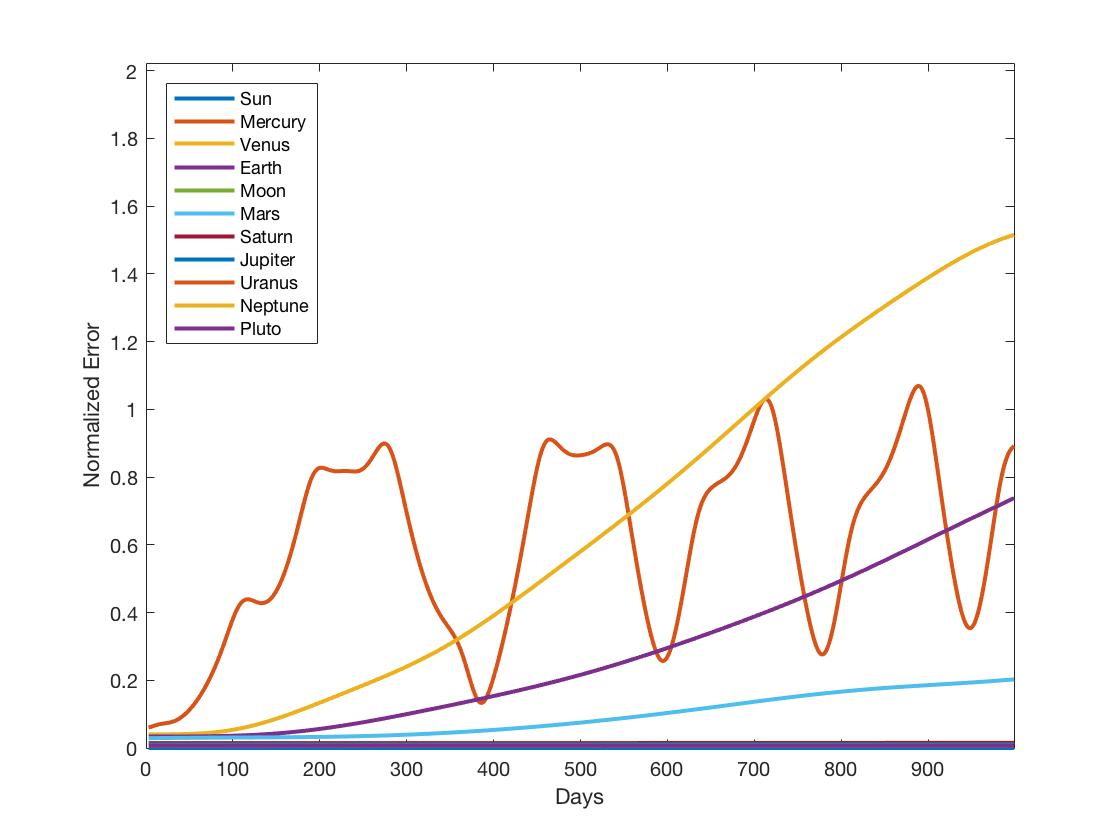

Timestep: 0.01 days:

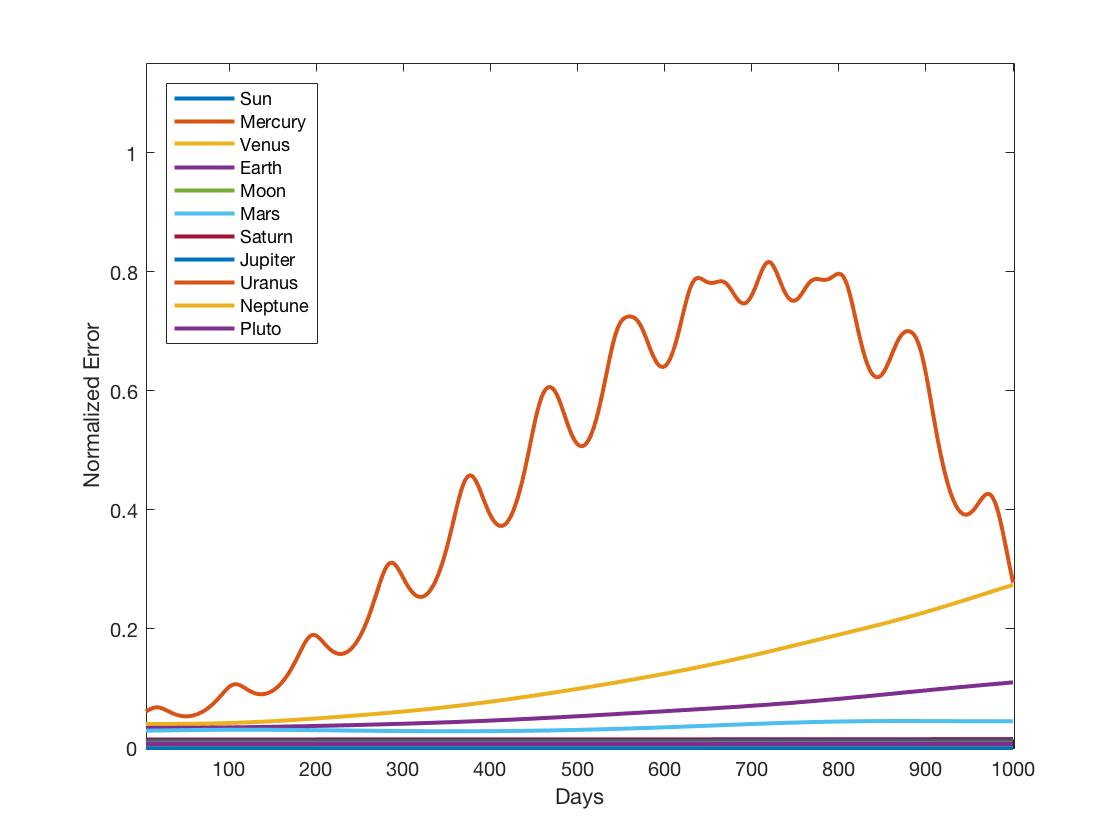

Timestep: 0.001 days:

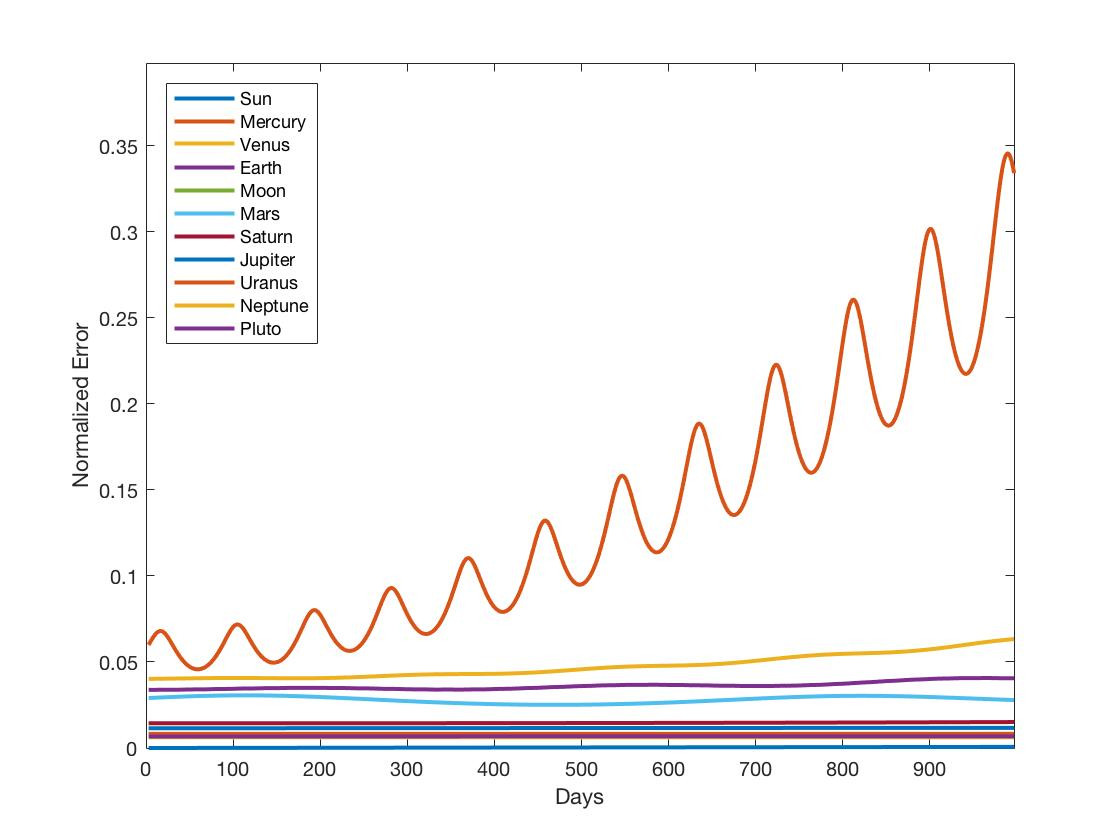

## ENCKE'S METHOD

*Additional files: enckes.m, enckesExample.avi*

**Background**

Encke's Method uses numerical integration as a function of time to predict how an initial osculating orbit will be affected by a perturbing object, as shown in Figure 2 below.

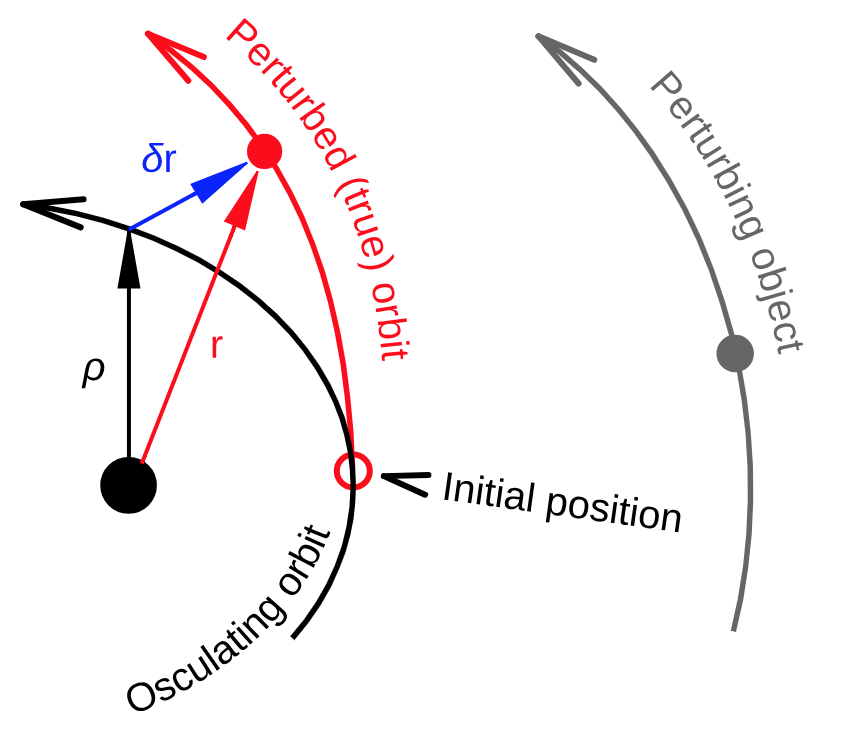

*Figure 2. The original orbit (black) is modified by the preturbing object's orbit (gray) to result in a new orbit (red). Image courtesy of *[*Wikimedia*](https://upload.wikimedia.org/wikipedia/commons/d/dc/Enckes_method-vector.svg)*. *

Mathematically, this can be modeled with 5 equations. Given rho as the radius of the osculating orbit, r as the radius of the perturbed orbit, and $\delta r$ is the variation from the osculating orbit:

$\delta \mathbf{r} = \mathbf{r} - \mathbf{\rho}$                                         (2)

$\ddot{\delta} \mathbf{r} = \ddot{\mathbf{r}} - \ddot{\mathbf{\rho}}$                                         (3)

Then given the gravitational constant G, mass of the central body M, mass of the perturbed body m, and acceleration 

$\ddot{\mathbf{r}} = \mathbf{a}\mathrm{_{per}} - \frac{G(M+m)}{\mathbf{|r|^3}}\mathbf{r}$                      (4)

$\ddot{\mathbf{\rho}} = -\frac{G(M+m)}{\mathbf{|\rho|^3}}\mathbf{\rho}$                            (5)

Equations 3-5 can be combined to develop the relationship:    

$\ddot{\delta}\mathbf{r} = \mathbf{a}\mathrm_{per} + G(M+m)\left(\frac{\mathbf{\rho}}{\rho^3} - \frac{\mathbf{r}}{r^3}\right)$       (6)

which is integrated to find $\delta \mathbf{r}$. Like Cowell's method, many significant digits are also needed to solve the difference of two similar vectors [4]. 

Advantages of Encke's method are reduced computation time/cost as well as better handling of large perturbations compared to Cowell's method. However, it is more complex than Cowell's method, and it requires the occasional updating of the orbit (i.e. rectification) before continuing integration [5].

**Encke's Method Example**

This example shows the small wobble on the Moon's orbit around Earth due to Venus.

addpath('Enckes');
[finalPos, finalVel] = enckes('enckesExample.avi', 365, 100, true, 4, 5, 3);
implay('enckesExample.avi')

Encke's method was limited by the long computational time needed to solve a second order differential equation. Approximations could be made to calculate results faster, but with less accuracy. This has been an area of further development and optimization in orbital modeling [5].

## **REFERENCES**

[1] W. M. Folkner et. al., “The Planetary and Lunar Ephemerides DE430 and DE431,” IPN Progress Report 42-196, Feb. 15, 2014. [Online serial]. Available: [NASA](https://ilrs.cddis.eosdis.nasa.gov/docs/2014/196C.pdf). [Accessed Feb. 20, 2019].

[2] NASA, “JPL Planetary and Lunar Ephemerides,” datasheet, Apr. 30, 2014. [Online]. Available: [NASA JPL](https://ssd.jpl.nasa.gov/?planet_eph_export.). [Accessed Feb 20, 2019].

[3] Herget, Paul. *The Computation of Orbits*. Ann Arbor, MI: Edwards Brothers, 1948. pp. 91. [Online]. Available: [Univeristy of California Berkley](https://babel.hathitrust.org/cgi/pt?id=uc1.$b664520;view=1up;seq=12).

[4] T. Fukushima, “Generalization of Encke's Method and its Application to the Orbital and Rotational Motions of Celestial Bodies,” *The Astronomical Journal*, vol. 112, no. 3, Sept. 1996. [Online serial]. Available: [Harvard University](http://adsbit.harvard.edu/cgi-bin/nph-iarticle_query?1996AJ....112.1263F&defaultprint=YES&filetype=.pdf). [Accessed Feb. 22, 2019].

[5] M.R. Delgado. Orbital Mechanics II. Class Lecture, Topic: “Modeling the Space Environment.” E.T.S.I. Aeronauticos, Universidad Politecnica de Madrid, Madrid, Spain, April 2008. [Online]. Available: [Polytechnic University of Madrid](http://ocw.upm.es/ingenieria-aeroespacial/modeling-the-space-environment/contenidos/material-de-clase/mse03_pertur_ocw.pdf). [Accessed March 1, 2019].

## DIVISION OF LABOR

All three team members worked on the project equally. The Cowell's Method code was primarily written by Caitlyn Caggia, and animations were created by Blaine Costello. The written tutorial was completed by Lakshmi Raju. All three members debugged code, and finalized the project together. 